addpath(genpath('../../helpers'));

fprintf('Loading FISSA .mat output at %s... \n', phoPipelineOptions.fissa.default_fissa_file_path)
loaded_fissa_data = load(phoPipelineOptions.fissa.default_fissa_file_path);
disp('done.')
        

num_pixels_per_mask = sum(final_data_explorer_obj.compMasks.Masks, [2 3]); 
table(num_pixels_per_mask)


% Consider finalDataStruct.anm265.session_20200120.imgData.comp20.fissa_ROI_regions
finalDataStruct.anm265.session_20200120.imgData.comp20.fissa_ROI_regions

cellfun(@size, finalDataStruct.anm265.session_20200120.imgData.comp20.fissa_ROI_regions,'UniformOutput',false)

% Maps across all trials for this cell_id:
cell_names = fieldnames(loaded_fissa_data.ROIs);
curr_cell_id_name = cell_names{3};
curr_cell_field_sizes = structfun(@size, loaded_fissa_data.ROIs.(curr_cell_id_name),'UniformOutput',false)

curr_cell_field_sizes = structfun(@size, loaded_fissa_data.ROIs.(curr_cell_id_name),'UniformOutput',false)
C = struct2cell(curr_cell_field_sizes)
% template_item = C{1};
% are_all_equal = cellfun(@(c) (isequal(c, template_item)), C)

[all_equal] = cellAllEqual(C)

curr_trial_fieldname = fieldnames(loaded_fissa_data.ROIs.(curr_cell_id_name)) % Just the first item
curr_trial_cell_ROI_regions = loaded_fissa_data.ROIs.(curr_cell_id_name).(curr_trial_fieldname{1})
curr_cell_region_field_sizes = cellfun(@size, curr_trial_cell_ROI_regions,'UniformOutput',false)
[all_equal] = cellAllEqual(curr_cell_region_field_sizes)


[cleaned_curr_trial_cell_ROI_regions] = cleanUp_Imported_FISSA_ROIs(curr_trial_cell_ROI_regions)


## Custom Plotting

% import PhoCustomPlotComponentBase
% 
% dates = datetime( 1970, 1, 1 ) : datetime( 1980, 1, 1 );
% rng default
% steps = [0, randn( size( dates(1:end-1) ) )];
% walk = cumsum( steps );
% f = exampleFigure( 'Name', 'PhoCustomPlotComponentBase Example' );
% LG = PhoCustomPlotComponentBase( 'Parent', f, ...
%                    'XData', dates, ...
%                    'YData', walk );
% set( LG.XLabel, 'String', 'Date', 'FontSize', 14 )
% set( LG.YLabel, 'String', 'Value', 'FontSize', 14 )
% set( LG.Title, 'String', 'PhoCustomPlotComponentBase', 'FontSize', 16 )
% LG.Grid = 'on';


% x = 1:1:100;
% y = 10*sin(x./5) + 8*sin(10.*x + 0.5);
% c = SmoothPlot('XData',x,'YData',y);

% x = 0:0.2:10;
% y = besselj(0,x);
% c = ConfidenceChart('XData',x,'YData',y,'ConfidenceMargin',0.15);

x = 1:1:100;
y = 10*sin(x./5)+8*sin(10.*x+0.5);
c = PhoSmoothLegendPlot('XData',x,'YData',y);

%%
% Use |c| to change the color of the smooth line to red. Notice that the legend also shows the new line color.

c.SmoothColor = [1 0 0];



## Build the Data Series

% % PlotData_Cartesian(plot_identifier, should_show, aColor, XData, YData, Colormap)
% 
% dataSeries = [PlotData_Cartesian('cellROI', true, 'r'),...
%     PlotData_Cartesian('neuropil', true, 'b')];
% 
% clear chart;
% 
% % hold off;
% % hold off;
% chart = PolygonRoiChart(dataSeries);
% 
% chart.dataSeries_labels


## New Plotting Way

activeCellROIIndex =21
plottingInfo.roi_alpha = 0.4;
plottingInfo.other_alpha = 0.3;

% plottingInfo.prevent_zoom_in = false;
plottingInfo.prevent_zoom_in = false;

% Note that this gets all comps (all sessions), not all ROIs
activeCompCells = final_data_explorer_obj.compMasks.Polygons; % Only want good polys, in the first session.
activeCompNeuropilCells = final_data_explorer_obj.compNeuropilMasks.Polygons; % Only want good polys, in the first session.

numLoop = length(activeCompCells);
% numLoop = length(final_data_explorer_obj.num_cellROIs);

% Loop through all cell ROIs
for i = 1:numLoop
    activeCompIndicies = final_data_explorer_obj.cellROIIndex_mapper.getCompListIndicies(activeCellROIIndex);
%     isCompMember = (sum(ismember(i, activeCompIndicies),'all') > 0);
%     isPlotted = isCompMember; % For testing whether all sessions are the same for a specific cellROI
    isPlotted = (i == activeCellROIIndex); % For testing a specific cellROI
    if isPlotted    
        currCellPolys = activeCompCells{i};
        currCellNeuropilPolys = activeCompNeuropilCells{i};
        
        chart = chart.update_comp_polys(currCellPolys, currCellNeuropilPolys);
    end
end

chart

## Old Plotting Way


activeCellROIIndex =17

activeCellROIIndex = 17

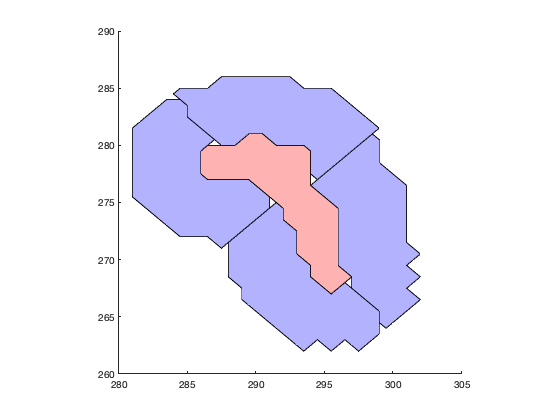

currCellPolys = 1×1 cell array
    {51×2 double}


currCellNeuropilPolys = 1×4 cell array
    {1×1 cell}    {1×1 cell}    {1×1 cell}    {1×1 cell}


	 poly[1]: 51


	 poly[1]: 55


	 poly[2]: 55


	 poly[3]: 51


	 poly[4]: 49





figH = figure(5);
clf(figH);

plottingInfo.roi_alpha = 0.4;
plottingInfo.other_alpha = 0.3;

% plottingInfo.prevent_zoom_in = false;
plottingInfo.prevent_zoom_in = false;

axis square
if plottingInfo.prevent_zoom_in
    xlim('manual');
    ylim('manual');
end

hold on;    


% Good, they appear to be the same within a single cellROI across sessions, thank god.

% Note that this gets all comps (all sessions), not all ROIs
activeCompCells = final_data_explorer_obj.compMasks.Polygons; % Only want good polys, in the first session.
activeCompNeuropilCells = final_data_explorer_obj.compNeuropilMasks.Polygons; % Only want good polys, in the first session.



numLoop = length(activeCompCells);
% numLoop = length(final_data_explorer_obj.num_cellROIs);

curr_session_index = 1;
% Loop through all cell ROIs
for i = 1:numLoop
    activeCompIndicies = final_data_explorer_obj.cellROIIndex_mapper.getCompListIndicies(activeCellROIIndex);
%     isCompMember = (sum(ismember(i, activeCompIndicies),'all') > 0);
%     isPlotted = isCompMember; % For testing whether all sessions are the same for a specific cellROI
    isPlotted = (i == activeCellROIIndex); % For testing a specific cellROI
    if isPlotted    
        currCellPolys = activeCompCells{i}
        currCellNeuropilPolys = activeCompNeuropilCells{i}
        
%         chart.update_comp_polys(currCellPolys, currCellNeuropilPolys);
        
%         curr_cellRoi_index = final_data_explorer_obj.cellROIIndex_mapper.getCompListIndicies(i);
        
    %     curr_cell_name = final_data_explorer_obj.cellROIIndex_mapper.uniqueComps{i};
%         curr_cell_name = final_data_explorer_obj.cellROIIndex_mapper.get(i);
        
        
        plottingInfo.curr_cell_name = 'temp';
        plottingInfo.patch_color = 'r';
        plottingInfo.plot_lines = true;
        [last_patches, last_lines, num_polys] = plotCellPolys(currCellPolys, plottingInfo);
        
        plottingInfo.patch_color = 'b';
        plottingInfo.plot_lines = true;
        [last_patches_neuropil, last_lines_neuropil, curr_cell_neuropil_num_polys] = plotCellPolys(currCellNeuropilPolys, plottingInfo);
        
%         fprintf('curr_cell_num_polys: %d, \t curr_cell_neuropil_num_polys: %d\n', curr_cell_num_polys, curr_cell_neuropil_num_polys);
        curr_session_index = curr_session_index + 1;
    end
    
end


% ps = polyshape([0 0 1 1],[1 0 0 1]);


function [last_patches, last_lines, num_polys] = plotCellPolys(polys, plottingInfo)
				% plotCellPolys:
                
                [poly_coord_data, num_points_per_poly, num_polys] = PolygonRoiChart.extractCellPerPolyCoordinates(polys, true);
				last_lines = gobjects(1, 1);
				last_patches = gobjects(1, 1);

				% Loop through all polygons within this cellROI
				for j = 1:num_polys
					curr_poly_coord_data = poly_coord_data{j};
% 					if iscell(curr_poly)
% 						fprintf('\t WARNING: poly[%d] is double wrapped!\n', j);
% 						curr_poly = curr_poly{1}; 
% 					end
					curr_x = curr_poly_coord_data(:, 2);
					curr_y = curr_poly_coord_data(:, 1);
					% Can add the x and y vectors as the next column of the deferred_plotting_matricies
					%%% on second thought, building x and y data vectors won't work well because the returned x and y are of variable size!
					%%%%%  True, but an almagamation mask can be added easily!
					%%%%%  OR, could concatenate all of them into x, y vectors. Nah, they'd still be of different length
					
% 					num_points = length(x);
% 					fprintf('\t poly[%d]: %d\n', j, num_points);
					
					is_first_poly_in_cell = (j == 1);
					if is_first_poly_in_cell
						last_patches(j) = fill(x, y, plottingInfo.patch_color, 'Tag', plottingInfo.curr_cell_name);
						alpha(plottingInfo.roi_alpha);
					else
						last_patches(j) = fill(x, y, plottingInfo.patch_color, 'Tag', plottingInfo.curr_cell_name);
						alpha(plottingInfo.other_alpha); 
					end
					
					if plottingInfo.plot_lines
						last_lines(j) = plot(x,y,'black','Tag', plottingInfo.curr_cell_name);
					else
						set(last_patches(j), 'EdgeColor','none');
					end
					
					if plottingInfo.prevent_zoom_in
						xlim([1 512]);
						ylim([1 512]);
					else
						axis square
					end
					
				end % end for
                
                
% 				num_polys = length(polys);
% 				last_lines = gobjects(num_polys, 1);
% 				last_patches = gobjects(num_polys, 1);
% 
% 				% Loop through all polygons within this cellROI
% 				for j = 1:num_polys
% 					curr_poly = polys{j};
% 					if iscell(curr_poly)
% 						fprintf('\t WARNING: poly[%d] is double wrapped!\n', j);
% 						curr_poly = curr_poly{1}; 
% 					end
% 					x = curr_poly(:, 2);
% 					y = curr_poly(:, 1);
% 					% Can add the x and y vectors as the next column of the deferred_plotting_matricies
% 					%%% on second thought, building x and y data vectors won't work well because the returned x and y are of variable size!
% 					%%%%%  True, but an almagamation mask can be added easily!
% 					%%%%%  OR, could concatenate all of them into x, y vectors. Nah, they'd still be of different length
% 					
% 					num_points = length(x);
% 					fprintf('\t poly[%d]: %d\n', j, num_points);
% 					
% 					is_first_poly_in_cell = (j == 1);
% 					if is_first_poly_in_cell
% 						last_patches(j) = fill(x, y, plottingInfo.patch_color, 'Tag', plottingInfo.curr_cell_name);
% 						alpha(plottingInfo.roi_alpha);
% 					else
% 						last_patches(j) = fill(x, y, plottingInfo.patch_color, 'Tag', plottingInfo.curr_cell_name);
% 						alpha(plottingInfo.other_alpha); 
% 					end
% 					
% 					if plottingInfo.plot_lines
% 						last_lines(j) = plot(x,y,'black','Tag', plottingInfo.curr_cell_name);
% 					else
% 						set(last_patches(j), 'EdgeColor','none');
% 					end
% 					
% 					if plottingInfo.prevent_zoom_in
% 						xlim([1 512]);
% 						ylim([1 512]);
% 					else
% 						axis square
% 					end
% 					
% 				end % end for
end

function [all_equal] = cellAllEqual(cellArray)
    template_item = cellArray{1};
    item_template_equal = cellfun(@(c) (isequal(c, template_item)), cellArray);
    all_equal = all(item_template_equal);
end
